# ELEC 4700 Assignment 4 Circuit Modeling

## Question 1

For Assignment 4, the resistor R3 is modelled by the semicondurctor region defined in the previous assignments. The bottleneck region formed creates a resistive element which could theoretically replace a resistor. The Electric Field of the bottlenecked region is shown below, demonstrating the cause of resistance from one side of the semiconductor to the other.

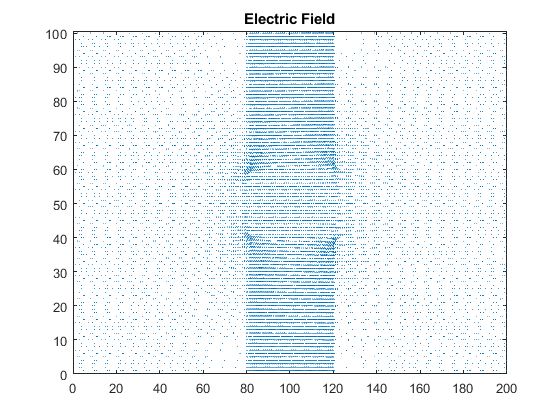

To extract a resisitance, the voltage and current relationship has to be modelled. To do so, the voltage across the region is swept from 0.V to 10V in 15 steps. Each voltage step the region is simulated over 150 time steps which was determined in the previous Assignment 3 to provide sufficient time for the region to reach its saturation point, wherein the current does not vary much as time continues.

% Questions 1 and 2

clc; close all; clear all;
set(0, 'DefaultFigureWindowStyle', 'docked')

% MC Settings
eCount = 10000;     % Total number of electrons
dt = 10e-15;        % Time step 10fs -> -(Width/100)/vT
nt = 150;           % Simulation steps
tStop = nt * dt;	% Stop Time

% Region settings
Length = 200e-9;
Width = 100e-9;

% Electron Properties
kB = 1.38066e-23;   % J/K 
m0 = 9.11e-31;      % Rest Mass
mn = 0.26*m0;       % Effective Mass
qe = 1.602e-19;     % Charge of an Electron (C)
ne = 10e19;         % Concentration (m^2)


% Thermal Velocity
Temp = 300;     % K
vT = sqrt((2*kB*Temp)/mn);

% Scattering Settings
% probability of scattering
toggleScatter = 1;    % Toggle Scattering OFF(0) ON(1)
tmin = 0.2e-12;
pScatter = 1 - exp(-dt/tmin);

% Bottleneck Settings
% Addition of box colliders to the sim
toggleDiffusive = 1; % 0 - Specular, 1 - Diffusive
% Providing opposing corners of desired boxes
box = [ % x1,y1, x2, y2 (Per box)
    0.8, 0, 1.2, 0.4;
    0.8, 0.6, 1.2, 1;
    ].*1e-7;

% Electric Field Settings
nx = 200;       % Number of divisions in X
ny = 100;       % ... in Y
boxL = 40;      % length of box along X
boxW = 40;      % width of box along Y
sigma = 0.001;  % Conductivity in the box
fdsoln = Assignment2_Q2(nx, ny, boxL, boxW, sigma);
vMap = reshape(fdsoln, [ny nx]);    % Reshaping Vector to a matrix
V = 0.1:0.7:10;

vstep = 1;
% Simulation loop
for voltage = V
    
    % Initializing all electrons with position and velocity
    % Electron object stores position, velocity and drift
    eObj = struct('x', 0, 'y', 0, 'vx', 0, 'vy', 0, 'vm', 0, 'vdx', 0);
    for i = 1 : eCount
        eObj(i).x = rand()*Length;
        eObj(i).y = rand()*Width;
        for b = 1:size(box,1)
            while eObj(i).x <= max(box(b,1),box(b,3)) && ...
                    eObj(i).x >= min(box(b,1),box(b,3)) && ...
                    eObj(i).y <= max(box(b,2),box(b,4)) && ...
                    eObj(i).y >= min(box(b,2),box(b,4))
                eObj(i).x = rand()*Length;
                eObj(i).y = rand()*Width;
            end
        end
        eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
        eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
        eObj(i).vm = sqrt(eObj(i).vx^2 + eObj(i).vy^2);
    end


    % Scaling voltage ... creating field
    [Ex,Ey] = gradient(-vMap*voltage);
    Ex = Ex ./ (Length/nx);    Ey = Ey ./ (Width/ny);	% Scaling E-Field
    Jn = 0; % will store current density
    
    
    t = 0;          % Init time
    counter = 2;    % Init Sim Counter
    while t < tStop

        t = t + dt;	% Incrementing Time

        % binning x and y coordinates
        [xpartbin, ~] = discretize([eObj(:).x], nx);
        [ypartbin, ~] = discretize([eObj(:).y], ny);

        prevX = [eObj(:).x];    % Previous X location
        prevY = [eObj(:).y];    % Previous Y location
        for i = 1 : eCount

            % Updating position
            eObj(i).x = prevX(i) + eObj(i).vx * dt;
            eObj(i).y = prevY(i) + eObj(i).vy * dt;

            % Scattering effect - Randomize direction/magnitude of velocity
            % Probability of scattering based on p.
            if pScatter > rand() && toggleScatter	% 'if true'
                eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
                eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
            end

            % Updating the velocities with the effect of E-Field
            Fx = qe * Ex(ypartbin(i), xpartbin(i));
            Fy = qe * Ey(ypartbin(i), xpartbin(i));
            eObj(i).vx = eObj(i).vx + 1/2*Fx/mn*dt;
            eObj(i).vy = eObj(i).vy + 1/2*Fy/mn*dt;

            % Drift velocity calculation
            dx = eObj(i).x - prevX(i);
            eObj(i).vdx = dx/dt;
            
            % Magnitude of velocity
            eObj(i).vm = sqrt(eObj(i).vx.^2 + eObj(i).vy.^2);

            % Box Collider Conditions.
            for b = 1:size(box,1)

                % Boundaries defined by coordinates
                boundL = min(box(b,1),box(b,3));    % Left Wall
                boundR = max(box(b,1),box(b,3));    % Right Wall
                boundT = max(box(b,2),box(b,4));    % Top Wall
                boundB = min(box(b,2),box(b,4));    % Bottom Wall

                % Conditions set by boundaires
                condL = prevX(i) <= boundL && eObj(i).x >= boundL;
                condR = prevX(i) >= boundR && eObj(i).x <= boundR;
                condB = prevY(i) <= boundB && eObj(i).y >= boundB;
                condT = prevY(i) >= boundT && eObj(i).y <= boundT;
                % Corner Cases
                condTC = condT && condR || condT && condL;
                condBC = condB && condR || condB && condL;

                % Checking Left and Right of the box First. 
                % Start by confirming if within Top and Bottom Boundaries
                if eObj(i).y <= boundT && eObj(i).y >= boundB
                    if condL || condR || condTC || condBC
                        if toggleDiffusive == 1 % If diffusion is toggled
                            posX = eObj(i).vx >= 0;	% Storing sign
                            posY = eObj(i).vy >= 0;
                            % re-thermalizing
                            eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
                            eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
                            % checking sign
                            if (eObj(i).vx >= 0) == posX
                                eObj(i).vx = -eObj(i).vx;
                            end
                            if (eObj(i).vy >= 0) ~= posY
                                eObj(i).vy = -eObj(i).vy;
                            end
                        else
                            eObj(i).vx = -eObj(i).vx;   % Just inverting
                        end
                        if condL    % Shifting reflection point
                            eObj(i).x = boundL - (eObj(i).x - boundL);
                        else
                            eObj(i).x = boundR + (boundR - eObj(i).x);
                        end
                    end
                end
                % Checking Top and Bottom of the box. 
                % Start by confirming if within Left and Right Boundaries
                if eObj(i).x <= boundR && eObj(i).x >= boundL
                    if condT || condB
                        if toggleDiffusive == 1
                            posX = eObj(i).vx >= 0;
                            posY = eObj(i).vy >= 0;  % Storing sign
                            % re-thermalizing
                            eObj(i).vx = (sqrt(vT^2 / 2)*randn(1,1));
                            eObj(i).vy = (sqrt(vT^2 / 2)*randn(1,1));
                            % checking sign
                            if (eObj(i).vx >= 0) ~= posX
                                eObj(i).vx = -eObj(i).vx;
                            end
                            if (eObj(i).vy >= 0) == posY
                                eObj(i).vy = -eObj(i).vy;
                            end
                        else
                            eObj(i).vy = -eObj(i).vy;
                        end
                        if condB    % Shifting reflection point
                            eObj(i).y = boundB - (eObj(i).y - boundB);
                        else
                            eObj(i).y = boundT + (boundT - eObj(i).y);
                        end
                    end
                end
            end


            % Top and Bottom Boundary Conditions
            if eObj(i).y > Width % y = 200nm boundary 
                diff = eObj(i).y - Width;
                eObj(i).y = Width - diff;
                eObj(i).vy = -eObj(i).vy;
            end
            if eObj(i).y < 0   % y = 0nm boundary
                diff = -eObj(i).y;
                eObj(i).y = diff;
                eObj(i).vy = -eObj(i).vy;
            end

            % Left hand and Right hand side Boundary Conditions
            if eObj(i).x > Length   % x = 100nm boundary
                eObj(i).x = eObj(i).x - Length;
            end
            if eObj(i).x < 0   % x = 0nm boundary
                eObj(i).x = eObj(i).x + Length;
            end

        end

        % Calculating drift current density over time
        Jn(:,counter) = qe*ne*mean([eObj(:).vdx]);

        counter = counter + 1;      % Incrementing Sim Counter
    end
    hold off

    avgJn(:,vstep) = mean(Jn);
    vstep = vstep + 1;
end

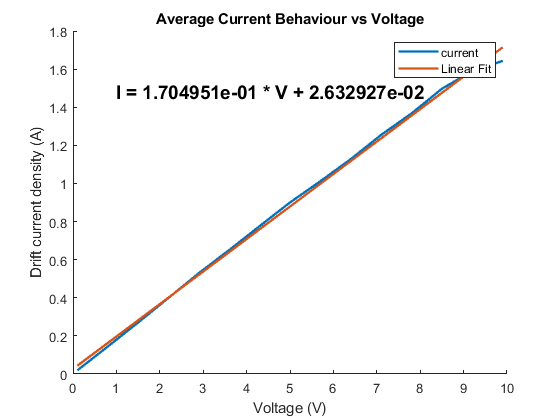


% Plotting drift current density and a linear fit
I = avgJn*Width; % A/m * m
p = polyfit(V,I,1);
I_poly = polyval(p, V);
figure(); hold on;
plot(V, I, 'LineWidth',1.75);   plot(V, I_poly, '-', 'LineWidth',1.75);
xlabel('Voltage (V)'), ylabel('Drift current density (A)');
title('Average Current Behaviour vs Voltage');
legend('current', 'Linear Fit');
caption = sprintf('I = %e * V + %e', p(1), p(2));
text(1, I(end)*0.9, caption, ...
    'FontSize', 14, 'Color', 'k', 'FontWeight', 'bold');

## Question 2

In simulating it is evident that the voltage and current relationship is linear. This simplifies the problem, as the resistor R3 could effectively be modelled by the slope of the relationship. A line was fit to the I-V curve and the conductance value can be extracted.

The inverse of the conduction provides a value for $\mathrm{R3}\approx 5\ldotp 89\Omega$

## Question 3

Using the following circuit, previously analyzed, a set of equations and unknowns can be determined

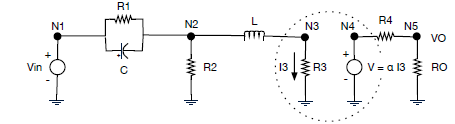

### Part a - Formulation

The following are the set of nodal equations for the 5 nodes prepared along with independent source relationships. 

Nodal Equations:

- 
$$\begin{array}{l}
0=I_E -\frac{V_2 -V_1 }{\mathrm{R1}}-\frac{d\left(V_2 -V_1 \right)}{\mathrm{dt}}C\\
\mathrm{Freq}\;\mathrm{domain}\to V_{\mathrm{in}} =I_E -\frac{V_2 -V_1 }{\mathrm{R1}}-j\omega C\left(V_2 -V_1 \right),V_1 \\
\;
\end{array}$$


- 
$$\begin{array}{l}
0=\frac{V_2 -V_1 }{\mathrm{R1}}+\frac{d\left(V_2 -V_1 \right)}{\mathrm{dt}}C+\frac{V_2 }{\mathrm{R2}}+I_L \\
\mathrm{Freq}\;\mathrm{domain}\to 0=\frac{V_2 -V_1 }{\mathrm{R1}}+j\omega C\left(V_2 -V_1 \right)+\frac{V_2 }{\mathrm{R2}}+\frac{V_2 -V_3 }{j\omega L}\\

\end{array}$$


- 
$$\begin{array}{l}
0=\frac{V_3 }{\mathrm{R3}}-I_L \\
\mathrm{Freq}\;\mathrm{domain}\to 0=\frac{V_3 }{\mathrm{R3}}-\frac{V_2 -V_3 }{j\omega L}
\end{array}$$


- 
$$0=$$

$$\frac{V_4 -V_5 }{\textrm{R4}}+I_{\alpha \;}$$


- 
$$0=\frac{V_4 -V_5 }{\mathrm{R4}}-\frac{V_5 }{\mathrm{R0}}$$


- 
$$V_1 =V_{\textrm{in}}$$


- 
$$I_L =\frac{V_2 -V_3 }{j\omega L}$$


- 
$$V_4 =\alpha I_3 ==0=\textrm{V4}-\alpha \;\frac{V_3 }{R_3 }$$


From the Equations the following matrices can be formed:

    
$$G=\left\lbrack \begin{array}{cccccccc}
\frac{1}{\textrm{R1}} & -\frac{1}{\textrm{R1}} & 0 & 0 & 0 & 1 & 0 & 0\\
-\frac{1}{\textrm{R1}} & \frac{1}{\textrm{R1}}+\frac{1}{\textrm{R2}} & 0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & \frac{1}{\textrm{R3}} & 0 & 0 & 0 & -1 & 0\\
0 & 0 & 0 & \frac{1}{\textrm{R4}} & -\frac{1}{\textrm{R4}} & 0 & 0 & 0\\
0 & 0 & 0 & -\frac{1}{\textrm{R4}} & \frac{1}{\textrm{R4}}+\frac{1}{\textrm{R0}} & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & -1 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & -\frac{\alpha \;}{\textrm{R3}} & 1 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


    
$$C=\left\lbrack \begin{array}{cccccccc}
C & -C & 0 & 0 & 0 & 0 & 0 & 0\\
-C & C & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & -L & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$
    
$$b=\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
V_{\textrm{in}} \\
0\\
0
\end{array}\right\rbrack$$
    
$$X=\left\lbrack \begin{array}{c}
V_1 \\
V_2 \\
V_3 \\
V_4 \\
V_5 \\
I_{\mathrm{in}} \\
I_L \\
I_{\alpha } 
\end{array}\right\rbrack$$


### Part b - DC and Frequnecy Domain Analysis of the circuit

With the MNA expressions in matrix form, the expression $\left(G+\mathrm{sC}\right)X=b$ can be used to solve for X which will provide the solutions to circuit. The following simulation shows a DC sweep of $V_{\textrm{in}}$ from -10V to 10V. The output votlage at node#5 and the voltage at node#3 are plotted against $V_{\textrm{in}}$. To perform the sweep, the frequency is set to 0 meaning the energy storage elements will be removed.

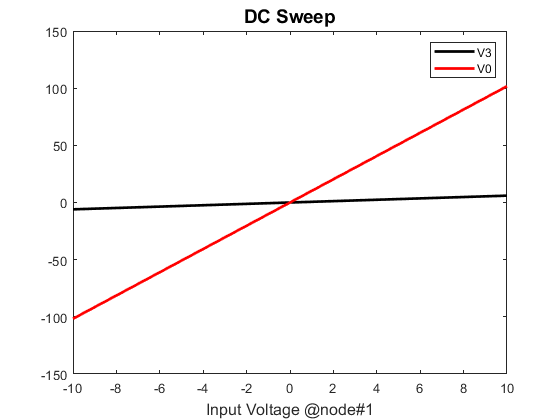

% Question 3

clc; clear all;
set(0, 'DefaultFigureWindowStyle', 'docked')
global G C F

R1 = 1;
R2 = 2;
R3 = 5.89;  % extracted from sim in part 1
R4 = 0.1;
R0 = 1000;
C1 = 0.25;
L1 = 0.2;
alpha = 100;

%-----------------------------------------------------------
% MNA Formulation:
%-----------------------------------------------------------
F = [0;0;0;0;0;1;0;0];  % Stimuli

G = [   % Conductance
    1/R1,-1/R1,0,0,0,1,0,0;
    -1/R1,1/R1+1/R2,0,0,0,0,1,0;
    0,0,1/R3,0,0,0,-1,0;
    0,0,0,1/R4,-1/R4,0,0,1;
    0,0,0,-1/R4,1/R4+1/R0,0,0,0;
    1,0,0,0,0,0,0,0;
    0,1,-1,0,0,0,0,0;
    0,0,-alpha/R3,1,0,0,0,0;
    ];

C = [   % Energy Storage
    C1,-C1,0,0,0,0,0,0;
    -C1,C1,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,-L1,0;
    0,0,0,0,0,0,0,0;
    ];

%-----------------------------------------------------------
% DC Sweep from -10V to 10V:
%-----------------------------------------------------------
s = 0;
vin = linspace(-10,10,100);
V3 = zeros(size(vin));
V0 = zeros(size(vin));
for i = 1:size(vin,2)
    V = (G+s.*C)\(F.*vin(i));   % Solving
    V3(i) = V(3);
    V0(i) = V(5);
end
figure('name',"DC Sweep")
plot(vin,V3,'k',"LineWidth",2);
hold on
plot(vin,V0,'r',"LineWidth",2);
hold off
xlabel('Input Voltage @node#1','FontSize',12);
legend('V3','V0'), title('DC Sweep', 'FontSize',14);

The circuit seems to amplify the output voltage with respect to the input voltage. The votlage transfer to the output is positive and can be related to the input.

The frequency response is tested by introducing the energy storage elements and sweeping the operating frequency to 100Hz. The output with respect to the radial frequency is as shown below.

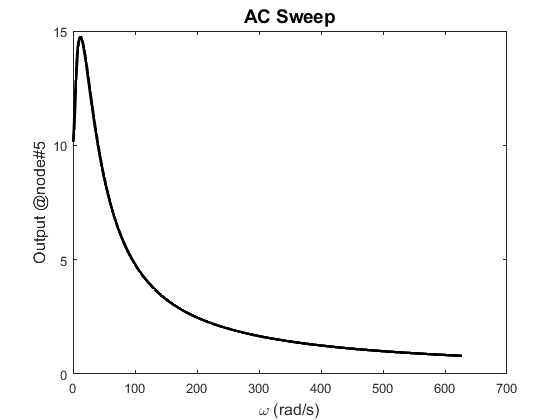

%-----------------------------------------------------------
% AC Sweep:
%-----------------------------------------------------------
f = linspace(0.001, 100, 100000);
V0 = zeros(size(f));
for i = 1:size(f,2)
    w = 2*pi*f(i);
    s = 1i*w;
    V = (G+s*C)\F;  % Solving
    V0(i) = V(5);
end


%-----------------------------------------------------------
% Plotting:
%-----------------------------------------------------------
% Plotting AC response of output magnitude
figure("Name","AC Sweep")
plot(2*pi*f,abs(V0),'k',"LineWidth",2);
title('AC Sweep', 'FontSize',14);
xlabel('\omega (rad/s)','FontSize',12);
ylabel('Output @node#5','FontSize',12);

For further insight into the output voltage to input voltage relationship, the gain, in dB, is plotted over the frequency range.

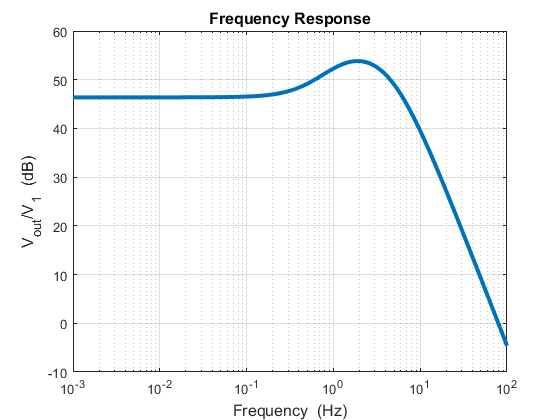

% Plotting AC response of gain
figure('Name','Freq-Response');
semilogx(f, 20*log(abs(V0)),'LineWidth',3);
grid;
title('Frequency Response', 'FontSize',12);
xlabel('Frequency  (Hz)','FontSize',12);
ylabel('V_{out}/V_{1}  (dB)','FontSize',12);

The frequency response of the circuit demonstrates a low pass filter with the effect of gain peaking occuring near the cut-off frequency.

The gain of the circuit can be influenced by some components in the circuit. Random perturbations on C using

a normal distribution with std = 0.05 at $\omega =\pi$ provides a distribution of the capacitor C and the resulting ditrtibution of gain.

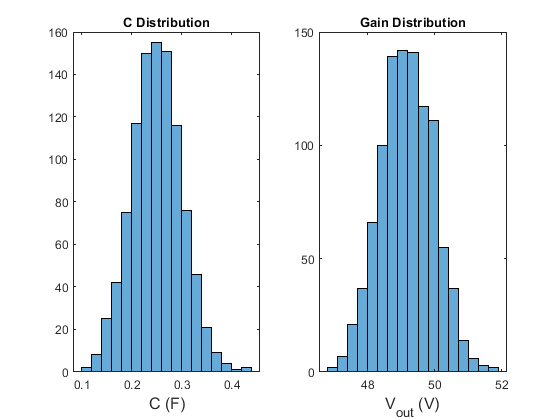

%-----------------------------------------------------------
% Monte Carlo Analysis of C:
%-----------------------------------------------------------
s = 1i*pi;
C1_dist = C1 + 0.05 * randn(1000,1);
V0 = zeros(size(C1_dist));
for i = 1:size(C1_dist,1)
    C(1,1) = C1_dist(i);
    C(1,2) = -C1_dist(i);
    C(2,1) = -C1_dist(i);
    C(2,2) = C1_dist(i);
    V = (G+s*C)\F;  % Solving
    V0(i) = V(5);
end
% Monte Carlo distribution
figure("Name","Monte Carlo Analysis of C")
subplot(1,2,1), histogram(C1_dist);
title('C Distribution', 'FontSize',14);
xlabel('C (F)','FontSize',12);
subplot(1,2,2), histogram(20*log(abs(V0)));
title('Gain Distribution', 'FontSize',14);
xlabel('V_{out} (V)','FontSize',12);

## Quesiton 4

### Transient Response of the circuit

The circuited presented is a linear RLC circuit showing a low pass filtering response with about 46dB of gain at near DC Frequencies.

To analyze the circuit in the time domain there are some methods and computing the transients. Below is the formulation using Finite Difference Backwards Euler method which calculates the next response at each time step using the previous time step provided some input simulus.

        
$$\left(G+\mathrm{sC}\right)X=b\Rightarrow C\;\frac{\mathrm{dX}\left(t\right)}{\mathrm{dt}}+\mathrm{GX}\left(t\right)=b\left(t\right)$$


Taking the incremental solution of the energy storage.

        
$$C\;\frac{X_n -X_{n-1} }{\Delta t}+{\textrm{GX}}_n =b\left(t_n \right)$$


Solving to capture the form of AX=b to solve for X=A\b. $X_{n-1}$ is known and $b\left(t_n \right)$ is known.

        
$$C\;\frac{X_n }{\Delta t}+{\textrm{GX}}_n =C\;\frac{X_{n-1} }{\Delta t}-b\left(t_n \right)$$


Simplifying.


$$\;\left(\frac{C}{\Delta t}+G\right)X_n =\;\frac{C}{\Delta t}X_{n-1} -b\left(t_n \right)$$


Solving.


$$\;X_n =\left(\frac{C}{\Delta t}+G\right)\backslash \frac{C}{\Delta t}X_{n-1} -b\left(t_n \right)$$


Using this expression the transient response can be solved provided an input (b). The following is simulating over 1 second with a 0.001 time step using 3 different types of input stimuli.

#### Part A: Step Response of the Circuit

The following demonstrates the step response of the circuit using backwards euler. The spectral contents is plotted following the transient response showing peak magnitude at 500Hz and the remaining contents of the step input.

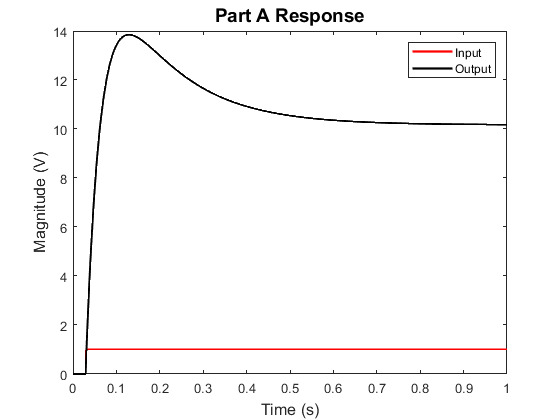

% Question 4

clc; clear all;
set(0, 'DefaultFigureWindowStyle', 'docked')
global G C b

R1 = 1;
R2 = 2;
R3 = 5.89;  % extracted from sim in part 1
R4 = 0.1;
R0 = 1000;
C1 = 0.25;
L1 = 0.2;
alpha = 100;

%-----------------------------------------------------------
% MNA Formulation:
%-----------------------------------------------------------
b = [0;0;0;0;0;1;0;0];  % Stimuli

G = [   % Conductance
    1/R1,-1/R1,0,0,0,1,0,0;
    -1/R1,1/R1+1/R2,0,0,0,0,1,0;
    0,0,1/R3,0,0,0,-1,0;
    0,0,0,1/R4,-1/R4,0,0,1;
    0,0,0,-1/R4,1/R4+1/R0,0,0,0;
    1,0,0,0,0,0,0,0;
    0,1,-1,0,0,0,0,0;
    0,0,-alpha/R3,1,0,0,0,0;
    ];

C = [   % Energy Storage
    C1,-C1,0,0,0,0,0,0;
    -C1,C1,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,-L1,0;
    0,0,0,0,0,0,0,0;
    ];

%-----------------------------------------------------------
% Time Settings:
%-----------------------------------------------------------
h = 1/1000;
t_vec = 0:h:1;

%-----------------------------------------------------------
% Backward Euler Part A: Step Response
%-----------------------------------------------------------
xn = [0;0;0;0;0;0;0;0];                 % initial values
voutA = zeros(size(G,1),numel(t_vec));  % Vector to hold outputs
vinA = zeros(1,numel(t_vec));           % Vector to hold inputs
vinA(1,1) = inputA(t_vec(1));
for n=1:numel(t_vec)-1
    voutA(:,n) = xn;                % Storing output
    vinA(n+1) = inputA(t_vec(n+1)); % Storing input
    bnn = b * vinA(n+1);            % Capturing next input
    xn = ((C./h) + G)\((C./h)*xn + bnn);    % BE Calculation
end
voutA(:,n+1) = xn;

%-----------------------------------------------------------
% Backward Euler Part B higher frequency: Sinusoidal Input
%-----------------------------------------------------------
f = 1/0.03; % Frequency in Hz
xn = [0;0;0;0;0;0;0;0];                 % initial values
voutB1 = zeros(size(G,1),numel(t_vec)); % Vector to hold outputs
vinB1 = zeros(1,numel(t_vec));          % Vector to hold inputs
vinB1(1,1) = inputB(f, t_vec(1));
for n=1:numel(t_vec)-1
    voutB1(:,n) = xn;
    vinB1(1,n+1) = inputB(f, t_vec(n+1));
    bnn = b * vinB1(1,n+1);
    xn = ((C./h) + G)\((C./h)*xn + bnn);
end
voutB1(:,n+1) = xn;

%-----------------------------------------------------------
% Backward Euler Part B lower frequency: Sinusoidal Input
%-----------------------------------------------------------
f = 1/0.3; % Frequency in Hz
xn = [0;0;0;0;0;0;0;0];                 % initial values
voutB2 = zeros(size(G,1),numel(t_vec)); % Vector to hold outputs
vinB2 = zeros(1,numel(t_vec));          % Vector to hold inputs
vinB2(1,1) = inputB(f, t_vec(1));
for n=1:numel(t_vec)-1
    voutB2(:,n) = xn;
    vinB2(1,n+1) = inputB(f, t_vec(n+1));
    bnn = b * vinB2(1,n+1);
    xn = ((C./h) + G)\((C./h)*xn + bnn);
end
voutB2(:,n+1) = xn;

%-----------------------------------------------------------
% Backward Euler Part C: Gaussian Pulse
%-----------------------------------------------------------
xn = [0;0;0;0;0;0;0;0];                 % initial values
voutC = zeros(size(G,1),numel(t_vec));  % Vector to hold outputs
vinC = zeros(1,numel(t_vec));           % Vector to hold inputs
vinC(1,1) = inputC(t_vec(1));
for n=1:numel(t_vec)-1
    voutC(:,n) = xn;
    vinC(1,n+1) = inputC(t_vec(n+1));
    bnn = b * vinC(1,n+1);
    xn = ((C./h) + G)\((C./h)*xn + bnn);
end
voutC(:,n+1) = xn;


%-----------------------------------------------------------
% Plotting A:
%-----------------------------------------------------------
% plotting the step Response of the circuit
figure("Name","Part A Response")
plot(t_vec, vinA,'red',"LineWidth",1.75);
hold on
plot(t_vec, voutA(5,:),'k',"LineWidth",1.75);
title('Part A Response', 'FontSize',14);
xlabel('Time (s)','FontSize',12);
ylabel('Magnitude (V)','FontSize',12);
legend({'Input','Output'});

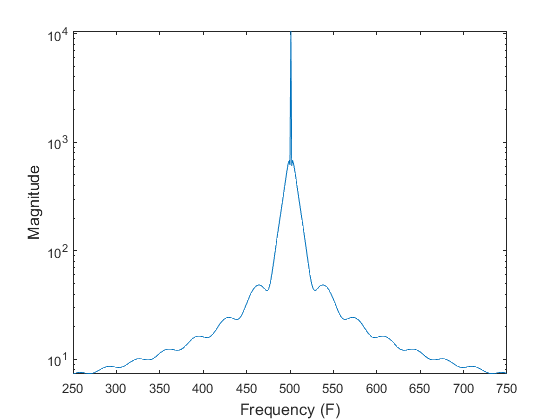


% plotting the frequency contents of the reponse
figure("Name","Part A Spectrum")
semilogy(abs(fftshift(fft(voutA(5,:)))))
xlabel('Frequency (F)','FontSize',12);
ylabel('Magnitude','FontSize',12);
xlim([250 750])

#### Part B.1: Sinusoidal Response of the Circuit at a high frequency

The following demonstrates the sinusoidal response of the circuit using backwards euler. The spectral contents is plotted following the transient response again showing a center frequency at 500Hz and the sine wave components at approx. f=33.33Hz from the center.

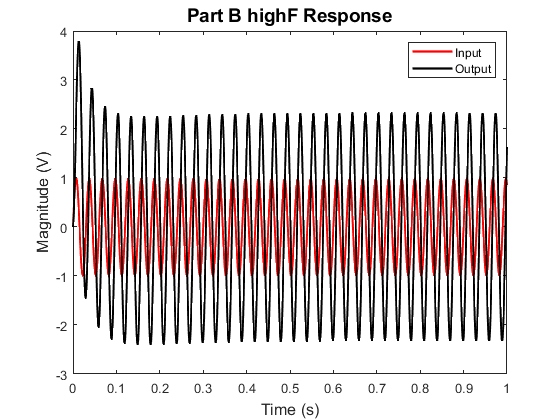


%-----------------------------------------------------------
% Plotting B:
%-----------------------------------------------------------
% plotting the Sinusoidal Response of the circuit
figure("Name","Part B highF Response")
plot(t_vec, vinB1,'red',"LineWidth",1.75);
hold on
plot(t_vec, voutB1(5,:),'k',"LineWidth",1.75);
title('Part B highF Response', 'FontSize',14);
xlabel('Time (s)','FontSize',12);
ylabel('Magnitude (V)','FontSize',12);
legend({'Input','Output'});

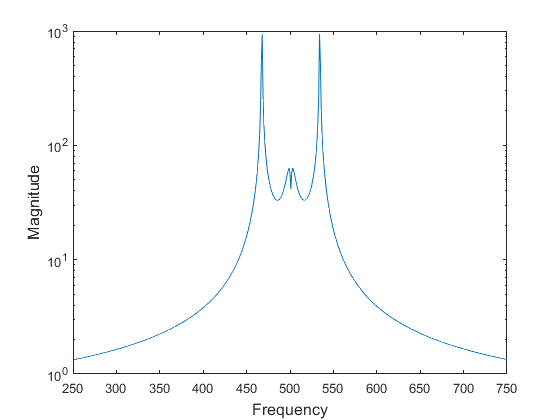


% plotting the frequency contents of the reponse
figure("Name","Part B highF Spectrum")
semilogy(abs(fftshift(fft(voutB1(5,:)))))
xlabel('Frequency','FontSize',12);
ylabel('Magnitude','FontSize',12);
xlim([250 750])

#### Part B.2: Sinusoidal Response of the Circuit at a lower frequency

The following demonstrates the sinusoidal response of the circuit using backwards euler. The spectral contents is plotted following the transient response again showing a center frequency at 500Hz and the sine wave components at approx. f=3.33Hz from the center. The slower frequency also shows the phase lagging on the output which is due to the LC components.

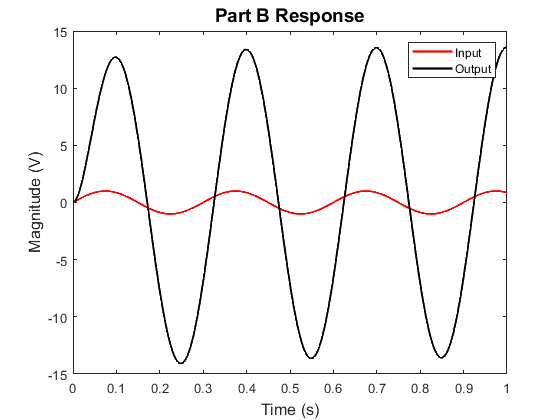


%-----------------------------------------------------------
% Plotting B:
%-----------------------------------------------------------
% plotting the Sinusoidal Response of the circuit w/ lower Frequency
figure("Name","Part B lowF Response")
plot(t_vec, vinB2,'red',"LineWidth",1.75);
hold on
plot(t_vec, voutB2(5,:),'k',"LineWidth",1.75);
title('Part B Response', 'FontSize',14);
xlabel('Time (s)','FontSize',12);
ylabel('Magnitude (V)','FontSize',12);
legend({'Input','Output'});

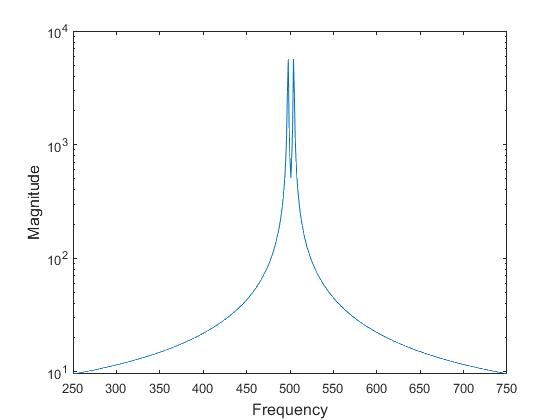


% plotting the frequency contents of the reponse
figure("Name","Part B lowF Spectrum")
semilogy(abs(fftshift(fft(voutB2(5,:)))))
xlabel('Frequency','FontSize',12);
ylabel('Magnitude','FontSize',12);
xlim([250 750])

#### Part C: Pulse Response of the Circuit

The following demonstrates the sinusoidal response of the circuit using backwards euler. The spectral contents is plotted following the transient response again showing a center frequency at 500Hz. The phase lag of the frequency response and the associated time to settle presents frequency compoenents into the spectrum.

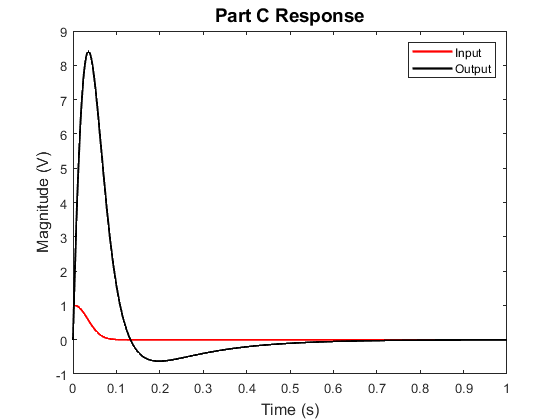


%-----------------------------------------------------------
% Plotting C:
%-----------------------------------------------------------
% plotting the Pulse Response of the circuit
figure("Name","Part C Response")
plot(t_vec, vinC,'red',"LineWidth",1.75);
hold on
plot(t_vec, voutC(5,:),'k',"LineWidth",1.75);
title('Part C Response', 'FontSize',14);
xlabel('Time (s)','FontSize',12);
ylabel('Magnitude (V)','FontSize',12);
legend({'Input','Output'});

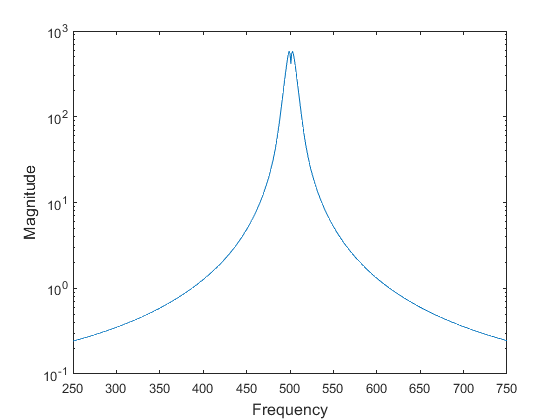



% plotting the frequency contents of the reponse
figure("Name","Part C Spectrum")
semilogy(abs(fftshift(fft(voutC(5,:)))))
xlabel('Frequency','FontSize',12);
ylabel('Magnitude','FontSize',12);
xlim([250 750])

### Transient Response due to Increased Time Step

Increasing the time step by 10 times (from 0.001 to 0.01) shown below causes the output to degrade and the higher frequency components to not show up. Decreasing further extremely limits the ability of the finite difference solver to reach proper results, causing the output to be jagged.

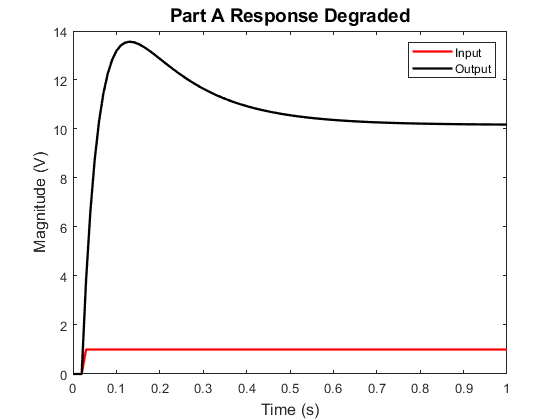

% Question 4

% Linear RLC Circuit
% Low Pass Filter with ~46dB of gain at DC and a corner frequency at 8Hz

clc; clear all;
set(0, 'DefaultFigureWindowStyle', 'docked')
global G C b

R1 = 1;
R2 = 2;
R3 = 5.89;  % extracted from sim in part 1
R4 = 0.1;
R0 = 1000;
C1 = 0.25;
L1 = 0.2;
alpha = 100;

%-----------------------------------------------------------
% MNA Formulation:
%-----------------------------------------------------------
b = [0;0;0;0;0;1;0;0];  % Stimuli

G = [   % Conductance
    1/R1,-1/R1,0,0,0,1,0,0;
    -1/R1,1/R1+1/R2,0,0,0,0,1,0;
    0,0,1/R3,0,0,0,-1,0;
    0,0,0,1/R4,-1/R4,0,0,1;
    0,0,0,-1/R4,1/R4+1/R0,0,0,0;
    1,0,0,0,0,0,0,0;
    0,1,-1,0,0,0,0,0;
    0,0,-alpha/R3,1,0,0,0,0;
    ];

C = [   % Energy Storage
    C1,-C1,0,0,0,0,0,0;
    -C1,C1,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,-L1,0;
    0,0,0,0,0,0,0,0;
    ];

%-----------------------------------------------------------
% Time Settings:
%-----------------------------------------------------------
h = 1/100;
t_vec = 0:h:1;

%-----------------------------------------------------------
% Backward Euler Part A: Step Response
%-----------------------------------------------------------
xn = [0;0;0;0;0;0;0;0];                 % initial values
voutA = zeros(size(G,1),numel(t_vec));  % Vector to hold outputs
vinA = zeros(1,numel(t_vec));           % Vector to hold inputs
vinA(1,1) = inputA(t_vec(1));
for n=1:numel(t_vec)-1
    voutA(:,n) = xn;                % Storing output
    vinA(n+1) = inputA(t_vec(n+1)); % Storing input
    bnn = b * vinA(n+1);            % Capturing next input
    xn = ((C./h) + G)\((C./h)*xn + bnn);    % BE Calculation
end
voutA(:,n+1) = xn;

%-----------------------------------------------------------
% Backward Euler Part B higher frequency: Sinusoidal Input
%-----------------------------------------------------------
f = 1/0.03; % Frequency in Hz
xn = [0;0;0;0;0;0;0;0];                 % initial values
voutB1 = zeros(size(G,1),numel(t_vec)); % Vector to hold outputs
vinB1 = zeros(1,numel(t_vec));          % Vector to hold inputs
vinB1(1,1) = inputB(f, t_vec(1));
for n=1:numel(t_vec)-1
    voutB1(:,n) = xn;
    vinB1(1,n+1) = inputB(f, t_vec(n+1));
    bnn = b * vinB1(1,n+1);
    xn = ((C./h) + G)\((C./h)*xn + bnn);
end
voutB1(:,n+1) = xn;

%-----------------------------------------------------------
% Backward Euler Part B lower frequency: Sinusoidal Input
%-----------------------------------------------------------
f = 1/0.3; % Frequency in Hz
xn = [0;0;0;0;0;0;0;0];                 % initial values
voutB2 = zeros(size(G,1),numel(t_vec)); % Vector to hold outputs
vinB2 = zeros(1,numel(t_vec));          % Vector to hold inputs
vinB2(1,1) = inputB(f, t_vec(1));
for n=1:numel(t_vec)-1
    voutB2(:,n) = xn;
    vinB2(1,n+1) = inputB(f, t_vec(n+1));
    bnn = b * vinB2(1,n+1);
    xn = ((C./h) + G)\((C./h)*xn + bnn);
end
voutB2(:,n+1) = xn;

%-----------------------------------------------------------
% Backward Euler Part C: Gaussian Pulse
%-----------------------------------------------------------
xn = [0;0;0;0;0;0;0;0];                 % initial values
voutC = zeros(size(G,1),numel(t_vec));  % Vector to hold outputs
vinC = zeros(1,numel(t_vec));           % Vector to hold inputs
vinC(1,1) = inputC(t_vec(1));
for n=1:numel(t_vec)-1
    voutC(:,n) = xn;
    vinC(1,n+1) = inputC(t_vec(n+1));
    bnn = b * vinC(1,n+1);
    xn = ((C./h) + G)\((C./h)*xn + bnn);
end
voutC(:,n+1) = xn;


%-----------------------------------------------------------
% Plotting A:
%-----------------------------------------------------------
% plotting the step Response of the circuit
figure("Name","Part A Response Degraded")
plot(t_vec, vinA,'red',"LineWidth",1.75);
hold on
plot(t_vec, voutA(5,:),'k',"LineWidth",1.75);
title('Part A Response Degraded', 'FontSize',14);
xlabel('Time (s)','FontSize',12);
ylabel('Magnitude (V)','FontSize',12);
legend({'Input','Output'});

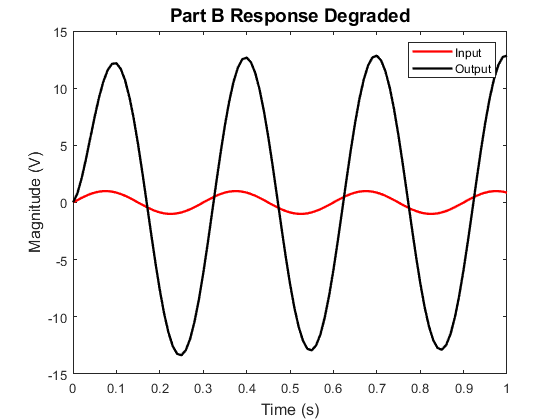



%-----------------------------------------------------------
% Plotting B:
%-----------------------------------------------------------
% plotting the Sinusoidal Response of the circuit w/ lower Frequency
figure("Name","Part B lowF Response Degraded")
plot(t_vec, vinB2,'red',"LineWidth",1.75);
hold on
plot(t_vec, voutB2(5,:),'k',"LineWidth",1.75);
title('Part B Response Degraded', 'FontSize',14);
xlabel('Time (s)','FontSize',12);
ylabel('Magnitude (V)','FontSize',12);
legend({'Input','Output'});

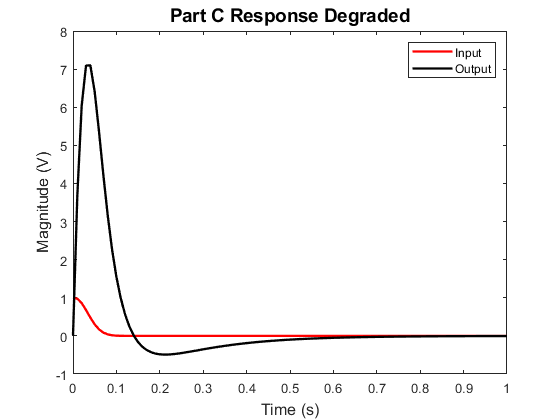



%-----------------------------------------------------------
% Plotting C:
%-----------------------------------------------------------
% plotting the Pulse Response of the circuit
figure("Name","Part C Response Degraded")
plot(t_vec, vinC,'red',"LineWidth",1.75);
hold on
plot(t_vec, voutC(5,:),'k',"LineWidth",1.75);
title('Part C Response Degraded', 'FontSize',14);
xlabel('Time (s)','FontSize',12);
ylabel('Magnitude (V)','FontSize',12);
legend({'Input','Output'});

## Quesiton 5

The circuit is modified to include thermal noise from resistor R3. A Capacitor Cn is added which will limit the bandwidth of noise. The following is the revised schematic.

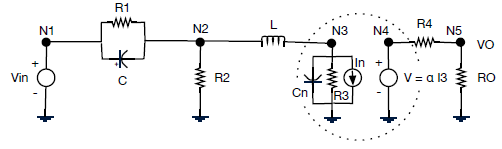

From the modification to the circuit the C and b matrices can be updated as underlined.

    
$$C=\left\lbrack \begin{array}{cccccccc}
C & -C & 0 & 0 & 0 & 0 & 0 & 0\\
-C & C & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & \underline{\textrm{Cn}}  & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & -L & 0\\
0 & 0 & \underline{-\alpha \textrm{Cn}}  & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$
    
$$b=\left\lbrack \begin{array}{c}
0\\
0\\
\underline{I_n } \\
0\\
0\\
V_{\textrm{in}} \\
0\\
0
\end{array}\right\rbrack$$
 

### Circuit with Noise Simulated

The input noise current $I_n$ is a random normally distributed function with a magnitude of 0.001. Using this noise the gaussian pulse response of the circuit was re-evaluated and the frequnecy contents are plotted as well.

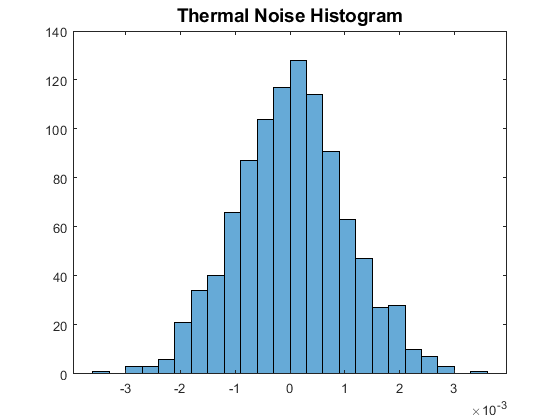

% Question 5

clc; clear all;
set(0, 'DefaultFigureWindowStyle', 'docked')
global G C b

R1 = 1;
R2 = 2;
R3 = 5.89;  % extracted from sim in part 1
R4 = 0.1;
R0 = 1000;
C1 = 0.25;
Cn = 0.00001;
L1 = 0.2;
alpha = 100;

%-----------------------------------------------------------
% MNA Formulation:
%-----------------------------------------------------------
b = [0;0;1;0;0;0;0;0];  % Stimuli noise source on N3

G = [   % Conductance
    1/R1,-1/R1,0,0,0,1,0,0;
    -1/R1,1/R1+1/R2,0,0,0,0,1,0;
    0,0,1/R3,0,0,0,-1,0;
    0,0,0,1/R4,-1/R4,0,0,1;
    0,0,0,-1/R4,1/R4+1/R0,0,0,0;
    1,0,0,0,0,0,0,0;
    0,1,-1,0,0,0,0,0;
    0,0,-alpha/R3,1,0,0,0,0;
    ];

C = [   % Energy Storage
    C1,-C1,0,0,0,0,0,0;
    -C1,C1,0,0,0,0,0,0;
    0,0,Cn,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,-L1,0;
    0,0,-alpha*Cn,0,0,0,0,0;
    ];

%-----------------------------------------------------------
% Time Settings:
%-----------------------------------------------------------
h = 1/1000;
t_vec = 0:h:1;

%-----------------------------------------------------------
% Backward Euler 
%-----------------------------------------------------------
xn = [0;0;0;0;0;0;0;0];
In = 0.001*randn(1,numel(t_vec));
vout = zeros(size(G,1),numel(t_vec));
vin = zeros(1,numel(t_vec));
vin(1,1) = In(1);
for n=1:numel(t_vec)-1
    vout(:,n) = xn;
    vin(n+1) = inputC(t_vec(n+1));
    bnn = b * In(n+1);
    bnn(6) = vin(n+1);
    xn = ((C./h) + G)\((C./h)*xn + bnn);
end
vout(:,n+1) = xn;


%-----------------------------------------------------------
% Plotting 
%-----------------------------------------------------------
% plotting the thermal noise
figure("Name","Thermal Noise Histogram")
histogram(In);
title('Thermal Noise Histogram', 'FontSize',14);

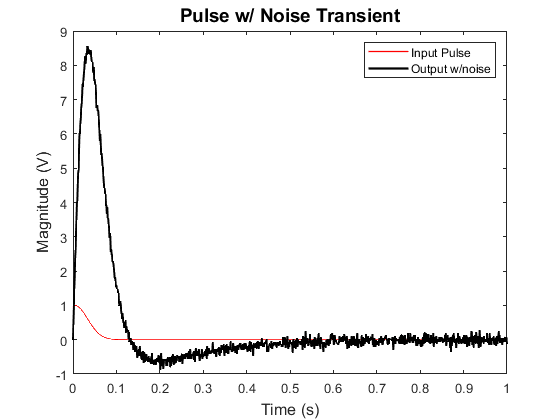


% plotting the input and Transient Response of the output
figure("Name","Transient Response")
plot(t_vec, vin,'r',"LineWidth",1);
hold on
plot(t_vec, vout(5,:),'k',"LineWidth",1.75);
title('Pulse w/ Noise Transient', 'FontSize',14);
xlabel('Time (s)','FontSize',12);
ylabel('Magnitude (V)','FontSize',12);
legend({'Input Pulse','Output w/noise'});

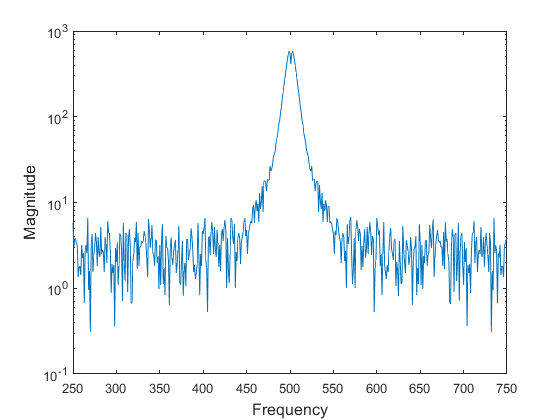


% plotting the frequency contents of the reponse
figure("Name","Response Spectrum")
semilogy(abs(fftshift(fft(vout(5,:)))))
xlabel('Frequency','FontSize',12);
ylabel('Magnitude','FontSize',12);
xlim([250 750])

Presenting noise into the system causes perturbations to afflict the signal over time. This noise can be well quantified when viewing the spectral contents, as the noise creates a noise floor on the side bands of the response.

### Circuit with Noise Simulated with BW Variation

A few simulation outputs with variations to the capacitor Cn are shown below. Vary the Cn should vary the possible frequency contents coupled to the output caused from the thermal noise.

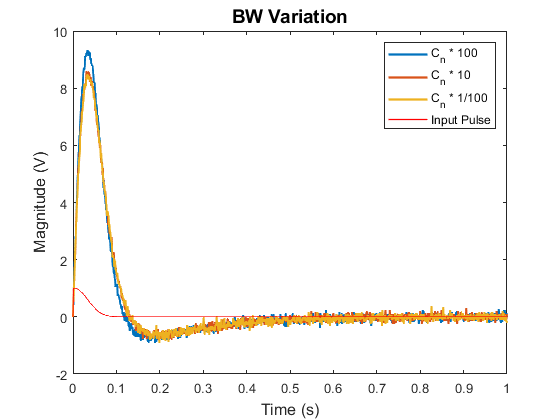

% Question 5

clc; clear all;
set(0, 'DefaultFigureWindowStyle', 'docked')
global G C b

R1 = 1;
R2 = 2;
R3 = 5.89;  % extracted from sim in part 1
R4 = 0.1;
R0 = 1000;
C1 = 0.25;
L1 = 0.2;
alpha = 100;

%-----------------------------------------------------------
% MNA Formulation:
%-----------------------------------------------------------
b = [0;0;1;0;0;0;0;0];  % Stimuli noise source on N3

G = [   % Conductance
    1/R1,-1/R1,0,0,0,1,0,0;
    -1/R1,1/R1+1/R2,0,0,0,0,1,0;
    0,0,1/R3,0,0,0,-1,0;
    0,0,0,1/R4,-1/R4,0,0,1;
    0,0,0,-1/R4,1/R4+1/R0,0,0,0;
    1,0,0,0,0,0,0,0;
    0,1,-1,0,0,0,0,0;
    0,0,-alpha/R3,1,0,0,0,0;
    ];

%-----------------------------------------------------------
% Time Settings:
%-----------------------------------------------------------
h = 1/1000;
t_vec = 0:h:1;

figure("Name","Transient Response")
for Cn = [0.001, 0.0001, 0.0000001]
    %-------------------------------------------------------
    % Backward Euler 
    %-------------------------------------------------------
    C = [   % Energy Storage
        C1,-C1,0,0,0,0,0,0;
        -C1,C1,0,0,0,0,0,0;
        0,0,Cn,0,0,0,0,0;
        0,0,0,0,0,0,0,0;
        0,0,0,0,0,0,0,0;
        0,0,0,0,0,0,0,0;
        0,0,0,0,0,0,-L1,0;
        0,0,-alpha*Cn,0,0,0,0,0;
        ];
    xn = [0;0;0;0;0;0;0;0];
    In = 0.001*randn(1,numel(t_vec));
    vout = zeros(size(G,1),numel(t_vec));
    vin = zeros(1,numel(t_vec));
    vin(1,1) = In(1);
    for n=1:numel(t_vec)-1
        vout(:,n) = xn;
        vin(n+1) = inputC(t_vec(n+1));
        bnn = b * In(n+1);
        bnn(6) = vin(n+1);
        xn = ((C./h) + G)\((C./h)*xn + bnn);
    end
    vout(:,n+1) = xn;
    plot(t_vec, vout(5,:), "LineWidth",1.75);
    hold on
end

plot(t_vec, vin,'r',"LineWidth",1);
title('BW Variation', 'FontSize',14);
xlabel('Time (s)','FontSize',12);
ylabel('Magnitude (V)','FontSize',12);
legend({'C_n * 100', 'C_n * 10', ...
    'C_n * 1/100', 'Input Pulse'});

Increasing the value of the capacitor Cn seems to have a large effect on the transient response. Then amount of perturbation in the signal seems to have increased slightly and the peak pulse response is increased. The effect is most likely from the increase in the RC time constant which on the plot is visible by the vact that the **blue** curve seems to be leading the others.

### Circuit with Noise Simulated with Time Step Variation

Then following is observations on how varying the time step will effect the transient response with the thermal noise present in the system. Two time steps are demonstrated, the nominal time step used in the previous simulations was 1ms.

% Question 5

clc; clear all;
set(0, 'DefaultFigureWindowStyle', 'docked')
global G C b

R1 = 1;
R2 = 2;
R3 = 5.89;  % extracted from sim in part 1
R4 = 0.1;
R0 = 1000;
C1 = 0.25;
Cn = 0.00001

Cn = 1.0000e-05

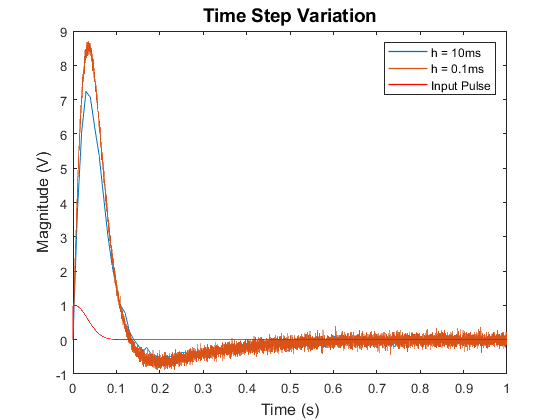

L1 = 0.2;
alpha = 100;

%-----------------------------------------------------------
% MNA Formulation:
%-----------------------------------------------------------
b = [0;0;1;0;0;0;0;0];  % Stimuli noise source on N3

G = [   % Conductance
    1/R1,-1/R1,0,0,0,1,0,0;
    -1/R1,1/R1+1/R2,0,0,0,0,1,0;
    0,0,1/R3,0,0,0,-1,0;
    0,0,0,1/R4,-1/R4,0,0,1;
    0,0,0,-1/R4,1/R4+1/R0,0,0,0;
    1,0,0,0,0,0,0,0;
    0,1,-1,0,0,0,0,0;
    0,0,-alpha/R3,1,0,0,0,0;
    ];
C = [   % Energy Storage
    C1,-C1,0,0,0,0,0,0;
    -C1,C1,0,0,0,0,0,0;
    0,0,Cn,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,0,0;
    0,0,0,0,0,0,-L1,0;
    0,0,-alpha*Cn,0,0,0,0,0;
    ];


figure("Name","Transient Response")
for h = [0.01, 0.0001]
    %-------------------------------------------------------
    % Backward Euler 
    %-------------------------------------------------------
    t_vec = 0:h:1;
    xn = [0;0;0;0;0;0;0;0];
    In = 0.001*randn(1,numel(t_vec));
    vout = zeros(size(G,1),numel(t_vec));
    vin = zeros(1,numel(t_vec));
    vin(1,1) = In(1);
    for n=1:numel(t_vec)-1
        vout(:,n) = xn;
        vin(n+1) = inputC(t_vec(n+1));
        bnn = b * In(n+1);
        bnn(6) = vin(n+1);
        xn = ((C./h) + G)\((C./h)*xn + bnn);
    end
    vout(:,n+1) = xn;
    plot(t_vec, vout(5,:), "LineWidth",1);
    hold on
end

plot(t_vec, vin,'r',"LineWidth",1);
title('Time Step Variation', 'FontSize',14);
xlabel('Time (s)','FontSize',12);
ylabel('Magnitude (V)','FontSize',12);
legend({'h = 10ms', 'h = 0.1ms', ...
    'Input Pulse'});

In increasing the time step, as seen previously, the output is degraded. With the noise presented, it seems not capture the full scope of the noise. In decreasing the timestep the transient result is much more refined, and so is the noise. The noise is being sampled effectively 10x more, which presents this much more visible gaussian noise that overcomes the signal. The FFT of the smaller time step is shown below, demonstrating the effect.

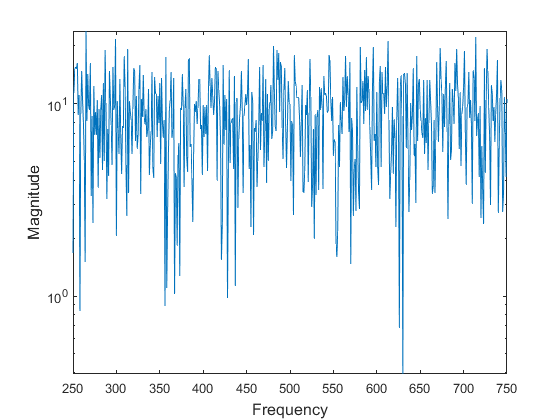

% plotting the frequency contents of the reponse
figure("Name","Response Spectrum")
semilogy(abs(fftshift(fft(vout(5,:)))))
xlabel('Frequency','FontSize',12);
ylabel('Magnitude','FontSize',12);
xlim([250 750])

## Question 6

The circuit simulated during this assignment did not contain any non-linear components. To increase the capabilities of the simulator this would need to be added. The MNA expression will change introducing the non-linear variable.

        
$$C\;\frac{\mathrm{dX}\left(t\right)}{\mathrm{dt}}+\mathrm{GX}\left(t\right)+\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\left(\mathit{\mathbf{t}}\right)\right)=b\left(t\right)$$


If for example the dependent source $V=\alpha I_3$ was instead $V=\alpha I_3 +{\beta I_3 }^2 +{\gamma I_3 }^3$, the higher order componets would need to be evalutated in time since they are non-linear. 

To evaluate non-linear compoents, the Newton Raphson method can be used. Iterating on the method can converge towards a result. The Newton iteration operates by starting with an initial condition and the resulting error from the initial condition can be computed using the solution of the MNA and the jacobian of the non-linear variable. The process can be iterated on until the error is almost indistinguishable, meaning the result is near and can be considered converged. The process would be done using the following equations.

        
$${\Rightarrow \;X}_{n+1} =X_n +\Delta X_n =X_n -\frac{\phi \left(X_n \right)}{\phi^{\prime } \left(X_n \right)}\;\;\;\;,n=0\;\mathrm{is}\;\mathrm{the}\;\mathrm{initial}\;\mathrm{condition}$$


                
$$\to \;\phi =0=\mathrm{GX}+f\left(X\right)-b$$


                
$$\to \;\phi^{\prime } =G+\frac{\mathrm{df}}{\mathrm{dx}}$$
